# Preparando o dataset

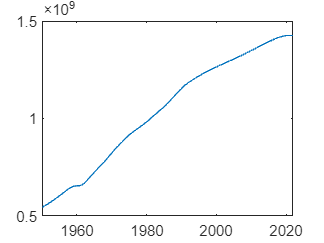

dados = readmatrix("ChinaPop2.csv");
x = dados(:, 1); %anos
y = dados(:, 2); %população
m = length(x);

plot(x,y);

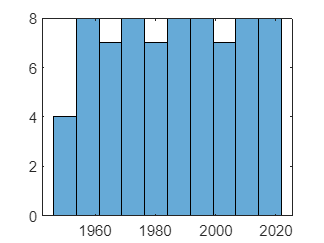

histogram(x,10);

# Normalização do dataset

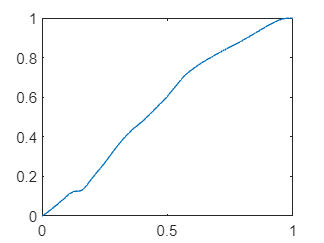

xnorm = (x - min(x))/(max(x) - min(x)); %formula normalização desvio padrão 1
ynorm = (y - min(y))/(max(y) - min(y));

plot(xnorm, ynorm);

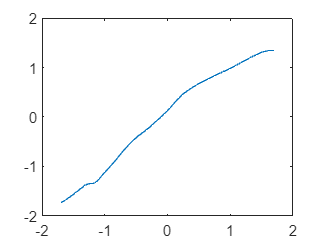


xnorm2 = (x - mean(x))/std(x);
ynorm2 = (y - mean(y))/std(y);

plot(xnorm2, ynorm2);

# Regressão linear simples sem normalização

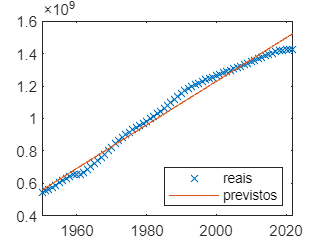

g = 1; %grau do polinomio para a regressão linear (simples = 1)
p = polyfit(x, y, g);

y_pred = polyval(p,x);

plot(x,y, 'x'); hold on;
plot(x, y_pred); hold off;
legend('reais', 'previstos', location='southeast');


sse = sum((y - y_pred).^2) %erros mt grandes pelo fato dos dados nao estarem normalizados

sse = 1.0549e+17

mae = mean(abs(y - y_pred))

mae = 3.2634e+07

mse = mean((y - y_pred).^2)

mse = 1.4451e+15

rmse = sqrt(mean((y - y_pred).^2))

rmse = 3.8014e+07


correl = corr(x,y)

correl = 0.9911

# Regressão linear simples com normalização

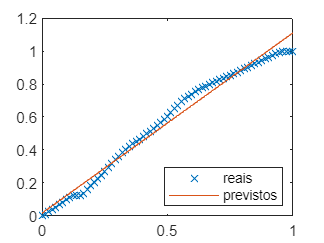

g = 1; %grau do polinomio para a regressão linear (simples = 1)
p = polyfit(xnorm, ynorm, g);

y_pred2 = polyval(p,xnorm);

plot(xnorm,ynorm, 'x'); hold on;
plot(xnorm, y_pred2); hold off;
legend('reais', 'previstos', location='southeast');


sse2 = sum((ynorm - y_pred2).^2) %valores aceitaveis

sse2 = 0.1356

mae2 = mean(abs(ynorm - y_pred2))

mae2 = 0.0370

mse2 = mean((ynorm - y_pred2).^2)

mse2 = 0.0019

rmse2 = sqrt(mean((ynorm - y_pred2).^2))

rmse2 = 0.0431


correl2 = corr(xnorm,ynorm)

correl2 = 0.9911

# Dividir o dataset para treino e teste RL simples

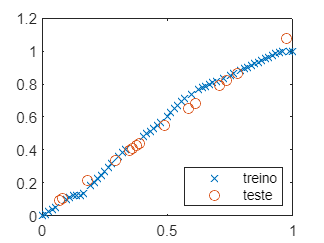

T = 0.8; %percentagem pra treino

idx = randperm(m);

x_train = xnorm(idx(1:round(T*m)));
y_train = ynorm(idx(1:round(T*m)));

x_test = xnorm(idx(round(T*m)+1:end));
y_test = ynorm(idx(round(T*m)+1:end));

g = 1; %grau do polinomio para a regressão linear (simples = 1)
p = polyfit(x_train, y_train, g);

y_pred_train = polyval(p,x_train);
y_pred_test = polyval(p,x_test); 

plot(x_train, y_train, 'x'); hold on;
plot(x_test,y_pred_test, 'o'); hold off;
legend('treino', 'teste', Location='southeast')


sse3 = sum((y_test - y_pred_test).^2)

sse3 = 0.0271

# Regressão não linear (polinomial)

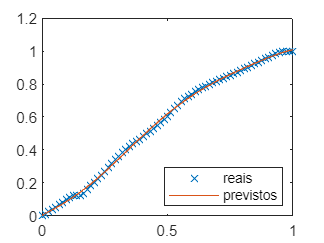

g = 6; %grau do polinomio para a regressão não linear (grau 2+)
p = polyfit(xnorm, ynorm, g);

y_pred_p2 = polyval(p,xnorm);

plot(xnorm, ynorm, 'x'); hold on;
plot(xnorm, y_pred_p2, '-'); hold off;
legend('reais', 'previstos', Location='southeast')


ssep2= sum((ynorm - y_pred_p2).^2)

ssep2 = 0.0060

# Gradiente descendente

LR = 0.01;
it = 100;

a = rand();
b = rand();

for i = 1:it
    y_pred_GD = a*xnorm+b;
    sseGD= sum((ynorm - y_pred_GD).^2);
    grad_a = 2 .* sum((y_pred_GD - ynorm).*xnorm);
    grad_b = 2 .* sum(y_pred_GD - ynorm);
    a = a - LR * grad_a;
    b = b - LR * grad_b;
end

disp(a);

    1.0938



disp(b);

    0.0165



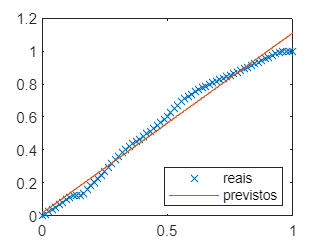


plot(xnorm,ynorm,'x'); hold on;
plot(xnorm, y_pred_GD); hold off;
legend('reais', 'previstos', Location='southeast');